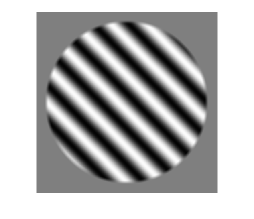

clc;clear all;close all
a=0:0.1:22*pi;
z=zeros(length(a));
for i=1:length(a)
    z(:,i)=a(i);
end

z_new=(sin(z)+1)/2; 

j=imrotate(z_new,45);
xx=250;
yy=700;
jr=j(xx:yy,xx:yy);
%imshow(jr)

figure(1)
E_out=f_Cut_for_circleMask(jr,225,225,200,0.5);
ave=fspecial('disk',5);
ff=imfilter(E_out,ave,'symmetric');
imshow(ff)

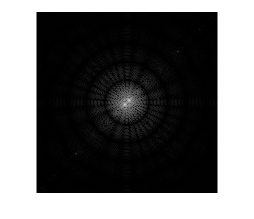


figure(2)
ftt=fftshift(fft2(ff));
fftshow(ftt)

function E_out = f_Cut_for_circleMask(E_in,Center_x,Center_y,Cir_Radiu,A)
% 函数功能：将输入矩阵按照像素值为单位进行圆形区域截取
% E_in：输入矩阵
% Center_x：截取圆形区域的中心坐标x
% Center_y：截取圆形区域的中心坐标x
% Cir_Radiu：截取圆形区域的截取半径像素值
% 注意：这三个参数均是像素值为单位
% A：截取后的其余部分赋值

[xnums,ynums] = size(E_in);
E_out = E_in;
for nx = 1:xnums
    for ny = 1:ynums
        if abs((nx - Center_x) + 1i*(ny - Center_y)) < Cir_Radiu
            E_out(nx, ny) = E_in(nx, ny);
        else
            E_out(nx, ny) = A;
        end
    end
end
end